%{
This notebook aims to predict if the full cell should be able to meet the
discharge power requirement of 27.36 mW/cm^2 with a current of 5C for a 10
second pulse, across all SOCs at 10 % increments (10,20,30,...)

Note that C/2 data is used, which overestimates the power output, since
there will be an increased overpotential that decreases the full cell
voltage on discharge when a 5C current is used
%}

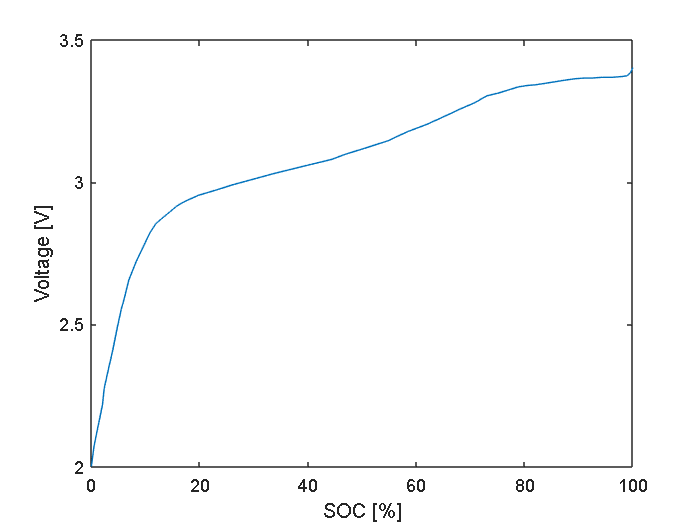

% Load full cell data
tableDchg = readtable("full_cell_cover2_discharge.csv");
cVecDchg = table2array(tableDchg(:,"capacity"));
vVecDchg = table2array(tableDchg(:,"voltage"));

% Plot voltage curve
SOC = 100 - cVecDchg / max(cVecDchg) * 100;
plot(SOC, vVecDchg)
ylabel("Voltage [V]")
xlabel("SOC [%]")

% Calculate the power output at each SOC value (10,20,30,...)
sampleSOCVec = 10:10:100;
current = 1.14*10; % mA/cm^2, equivalent to 5C
powerRequirement = 27.36; % mW/cm^2
fullCellArea = 4752; % cm^2

powerVec = [];

for sampleSOC = sampleSOCVec

    voltage = interp1(SOC, vVecDchg, sampleSOC);
    power = current*voltage;
    powerVec = [powerVec power];

end

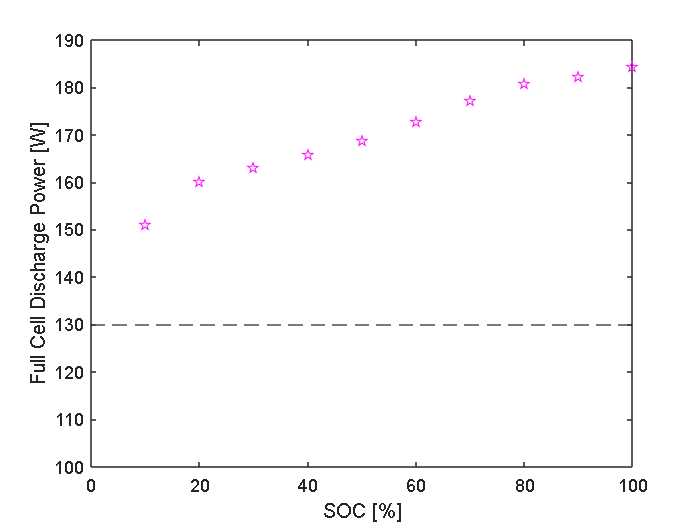

% Plot discharge power vs. customer requirement power
plot(sampleSOCVec, powerVec*fullCellArea/1000, 'p', color="magenta")
hold on
yline(powerRequirement*fullCellArea/1000, 'k--')
ylabel("Full Cell Discharge Power [W]")
xlabel("SOC [%]")
ylim([100,190])